% plant_model.m
% Defines the throttle-motor transfer function and plots open-loop response

clc;
clear;
close all;

% Define plant parameters
K = 1;          
tau = 0.5;      

% Create transfer function
G = tf(K, [tau 1]);

disp('Transfer Function G(s):');

Transfer Function G(s):


G


G =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.
Model Properties



% Plot open-loop step response
figure;
step(G);
grid on;
title('Open-Loop Motor Step Response');
xlabel('Time (seconds)');
ylabel('Motor Speed');

% Step response info
info = stepinfo(G);
disp('Open-loop Step Response Info:');

Open-loop Step Response Info:


disp(info);

         RiseTime: 1.0985
    TransientTime: 1.9560
     SettlingTime: 1.9560
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 3.6611



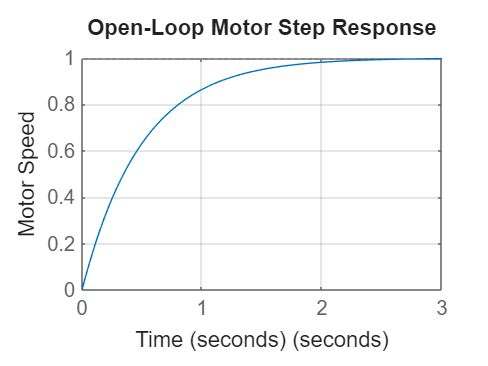


% === YOUR CUSTOM SAVE PATH ===
save_path = 'C:\Users\SABEE\OneDrive\Desktop\Attachments\Desktop\sabeeh\My projects\Control systems\end_eval';

% Save plot
saveas(gcf, fullfile(save_path, 'open_loop_response.png'));